# Gráficas

## Gráficas en 2-D

### Ejercicio 1

La distancia que recorre un proyectil cuando se dispara a un ángulo $\theta$ es función del tiempo y se puede dividir en distancias horizontal y vertical de acuerdo con las  fórmulas:


$$\textrm{Horizontal}\left(t\right)={\textrm{tv}}_0 \;\cos \left(\theta \right)$$



$$\textrm{Vertical}\left(t\right)={\textrm{tv}}_0 \;\textrm{sen}\left(\theta \right)-\frac{1}{2}{\textrm{gt}}^2$$


donde $\textrm{Horizontal}$ es la distancia recorrida en la dirección $x$, $\textrm{Vertical}$ es la distancia recorrida en la dirección $y$, $v_0$ es la velocidad inicial, $g$ es la aceleración debida a gravedad, $9\ldotp 8\;\mathrm{m}/{\mathrm{s}}^2$ y $t$ es el tiempo ($\mathrm{s}$).

Suponga que el proyectil descrito se dispara con una velocidad inicial de $100\;\mathrm{m}/\mathrm{s}$ y un  ángulo de lanzamiento de $\pi /4\;\left(45\degree \right)$. Encuentre la distancia recorrida tanto horizontal como verticalmente (en las direcciones $x$ y $y$) para tiempos desde 0 hasta 20 segundos.

- Realizar la gráfica de la distancia horizontal contra tiempo.

- Realizar la gráfica de la distancia vertical contra el tiempo.

- Realizar la gráfica de la distancia horizontal y vertical contra el tiempo utilizando la función `yyaxis`.

- Realizar las dos gráficas anteriores en una sola ventana utilizando la función `subplot`.

¿Cuál de las dos formas de visualizar las gráficas, literal 3 y 4, es más adecuada? ¿Por qué?

Añadir título, etiquetas, cuadrícula, etc.; a todas las gráficas.

*Ejercicio modificado de Moore, 2007.*

### Solución


$$\textrm{Horizontal}\left(t\right)={\textrm{tv}}_0 \;\cos \left(\theta \right)$$
        
$$\textrm{Vertical}\left(t\right)={\textrm{tv}}_0 \;\textrm{sen}\left(\theta \right)-\frac{1}{2}{\textrm{gt}}^2$$


% Datos del problema

v0 = 100; % velocidad inicial [m/s]
theta = pi/4; % ángulo [rad]
g = 9.8; % [m/s^2]
rangoT = linspace(0,20);    % tiempo [s]

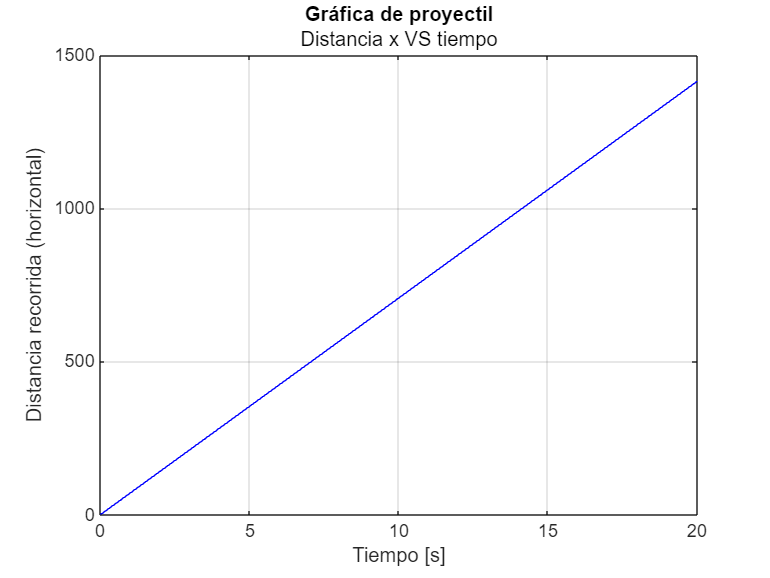

% Inciso 1
dist_x = rangoT .* v0 .* cos(theta);

cla ax reset;
plot(rangoT, dist_x, "Color","b");
xlabel("Tiempo [s]")
ylabel("Distancia recorrida (horizontal)");
title("Gráfica de proyectil");
subtitle("Distancia x VS tiempo")
grid on;

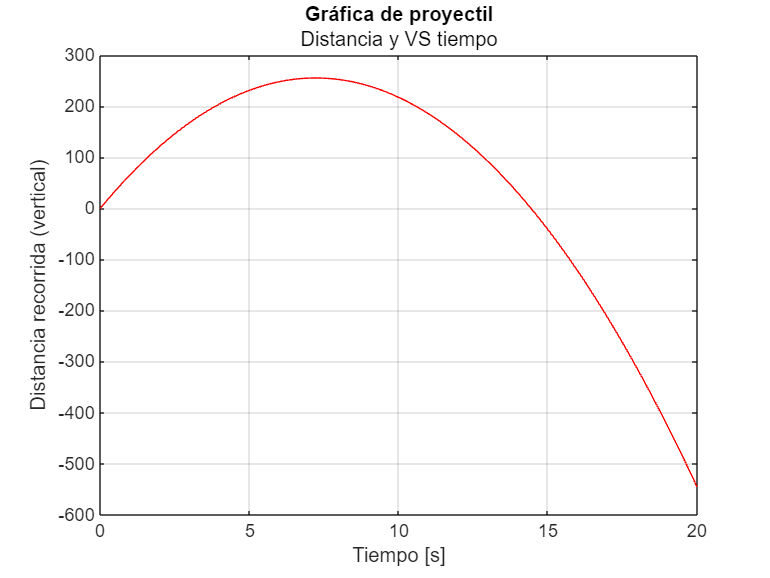

% Inciso 2
dist_y = rangoT * v0 * sin(theta) - 0.5 * g * rangoT.^2;

cla ax reset;
plot(rangoT, dist_y, "r");
xlabel("Tiempo [s]")
ylabel("Distancia recorrida (vertical)");
title("Gráfica de proyectil");
subtitle("Distancia y VS tiempo")
grid on;

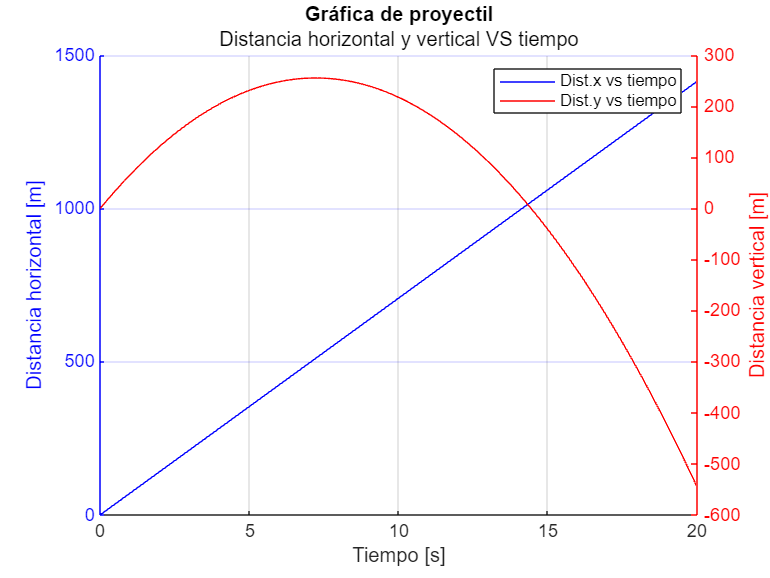

% Inciso 3
dist_x = rangoT .* v0 .* cos(theta);
dist_y = rangoT * v0 * sin(theta) - 0.5 * g * rangoT.^2;

cla ax reset;
hold on

yyaxis left
plot(rangoT,dist_x,"DisplayName","Dist.x vs tiempo","Color","b");
ylabel("Distancia horizontal [m]")
eje = gca;
eje.YColor = "b"

yyaxis right
plot(rangoT,dist_y,"DisplayName","Dist.y vs tiempo","Color","r");
ylabel("Distancia vertical [m]")
eje = gca;
eje.YColor = "r"

title("Gráfica de proyectil");
subtitle("Distancia horizontal y vertical VS tiempo")
grid on;

xlabel("Tiempo [s]")

legend;
hold off

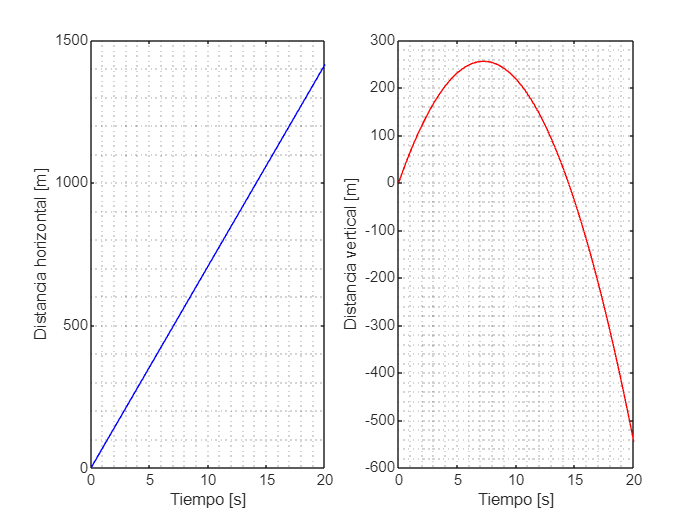

% Inciso 4
dist_x = rangoT .* v0 .* cos(theta);
dist_y = rangoT * v0 * sin(theta) - 0.5 * g * rangoT.^2;

cla ax reset;
subplot(1,2,1)
plot(rangoT,dist_x,"DisplayName","Dist.x vs tiempo","Color","b");
ylabel("Distancia horizontal [m]");
xlabel("Tiempo [s]");
grid minor;

subplot(1,2,2)
plot(rangoT,dist_y,"DisplayName","Dist.y vs tiempo","Color","r");
ylabel("Distancia vertical [m]");
xlabel("Tiempo [s]");

grid minor;

% Comentario
% La configuración gráfica del inciso 3 es más adecuada ya que brinda
% información que se puede analizar de forma conjunta de manera intuitiva e
% interpretar los resultados (punto de intersección).

### Ejercicio 2

De acuerdo con la *ley de Moore* (una observación hecha en 1965 por Gordon Moore, cofundador de *Intel Corporation*), el número de transistores que encajaría por pulgada cuadrada en un circuito integrado semiconductor se duplica aproximadamente cada 18 meses. El año 2005 fue el 40 aniversario de la ley. Durante los últimos 40 años, su proyección se ha satisfecho de manera consistente. En 1965, la entonces tecnología de avanzada permitía 30 transistores por pulgada cuadrada. La ley de Moore dice que la densidad de transistores se puede predecir mediante


$$d\left(t\right)=30\left(2^{t/1\ldotp 5} \right)$$


donde $t$ se mide en años.

- Sea $t=0$ la representación del año 1965 y $t=45$ la representación de 2010. Use  este modelo para calcular el número predicho de transistores por pulgada cuadrada para los 45 años desde 1965 hasta 2010. Sea $t$ el aumento en incrementos de 1.5 años. Muestre los resultados en una tabla con 2 columnas, una para el año y otra para el número de transistores.

- Con la característica `subplot`, grafique los datos en una gráfica lineal $x-y$, una gráfica $x\;\textrm{semilog}$, una gráfica $y\;\textrm{semilog}$ y una gráfica $\log -\log$. Asegúrese de poner título y etiqueta a los ejes.

¿Cuál de todas las gráficas del literal 2 es la más adecuada para visualizar los datos?

**Recomendación:** Utilizar las funciones `semilogx`, `semilogy` y `loglog` (consultar en la documentación).

*Ejercicio tomado de Moore, 2007.*

### Solución

% Inciso 1
t = 0:1.5:45;

anno = 1965 + t;
d = 30 * (2.^(t/1.5));

tablaDatos = table(anno', d');
tablaDatos.Properties.VariableNames = ["Año" "d"];
disp(tablaDatos);

     Año          d     
    ______    __________

      1965            30
    1966.5            60
      1968           120
    1969.5           240
      1971           480
    1972.5           960
      1974          1920
    1975.5          3840
      1977          7680
    1978.5         15360
      1980         30720
    1981.5         61440
      1983    1.2288e+05
    1984.5    2.4576e+05
      1986    4.9152e+05
    1987.5    9.8304e+05
      1989    1.9661e+06
    1990.5    3.9322e+06
      1992    7.8643e+06
    1993.5    1.5729e+07
      1995    3.1457e+07
    1996.5    6.2915e+07
      1998    1.2583e+08
    1999.5    2.5166e+08
      2001    5.0332e+08
    2002.5    1.0066e+09
      2004    2.0133e+09
    2005.5    4.0265e+09
      2007    8.0531e+09
    2008.5    1.6106e+10
      2010    3.2212e+10



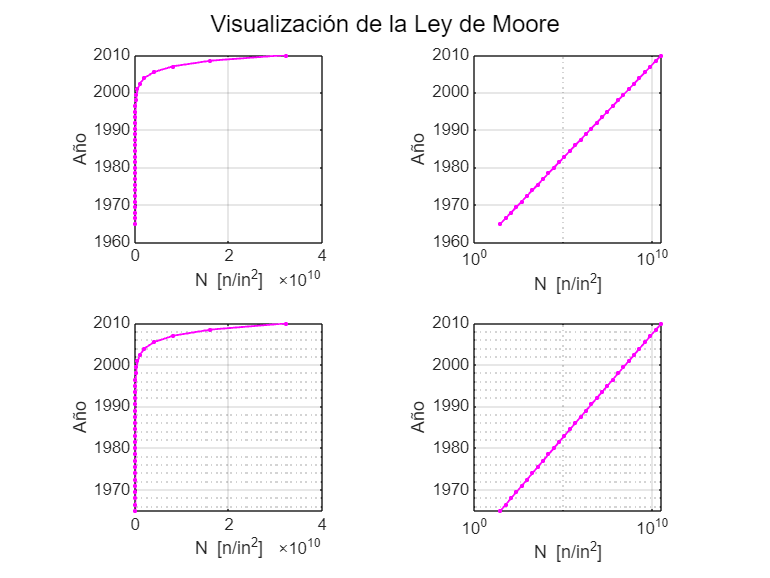

% Inciso 2

cla ax reset;

subplot(2,2,1)
plot(d,anno,"Color","m","LineStyle","-","LineWidth",1,"Marker",".","MarkerSize",7);
xlabel("N [n/in^2]");
ylabel("Año");
grid on;
axis("square");

subplot(2, 2, 2);
semilogx(d,anno,"Color","m","LineStyle","-","LineWidth",1,"Marker",".","MarkerSize",7);
xlabel("N [n/in^2]");
ylabel("Año");
grid on;
axis("square");

subplot(2, 2, 3);
semilogy(d,anno,"Color","m","LineStyle","-","LineWidth",1,"Marker",".","MarkerSize",7);
xlabel("N [n/in^2]");
ylabel("Año");
grid on;
axis("square");

subplot(2, 2, 4);
loglog(d,anno,"Color","m","LineStyle","-","LineWidth",1,"Marker",".","MarkerSize",7);
xlabel("N [n/in^2]");
ylabel("Año");
grid on;
axis("square");

sgtitle("Visualización de la Ley de Moore");

% Comentario
% La gráfica mas adecuada para este caso es la número dos "semilogx"

### Ejercicio 3

La deformación de muchos metales cambia sus propiedades físicas. En un proceso llamado *trabajo en frío*, el metal se deforma intencionalmente para hacerlo más fuerte. Los siguientes datos tabulan tanto la fortaleza como la ductilidad de un metal que se  trabajó en frío a diferentes grados:

**Figura 1.** Datos del proceso *trabajo en frío*.

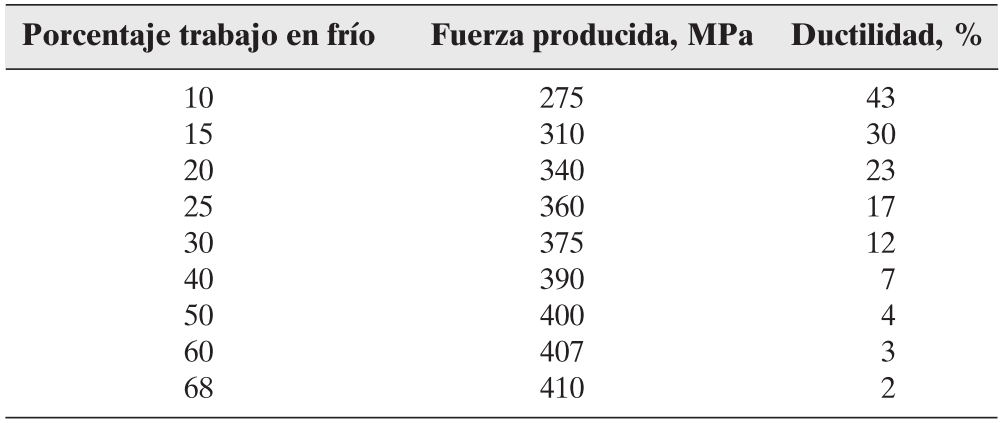

*Tomado de MATLAB para ingenieros de Holly Moore.*

Graficar estos datos en una sola gráfica $x-y$ con dos ejes $y$.

### Solución

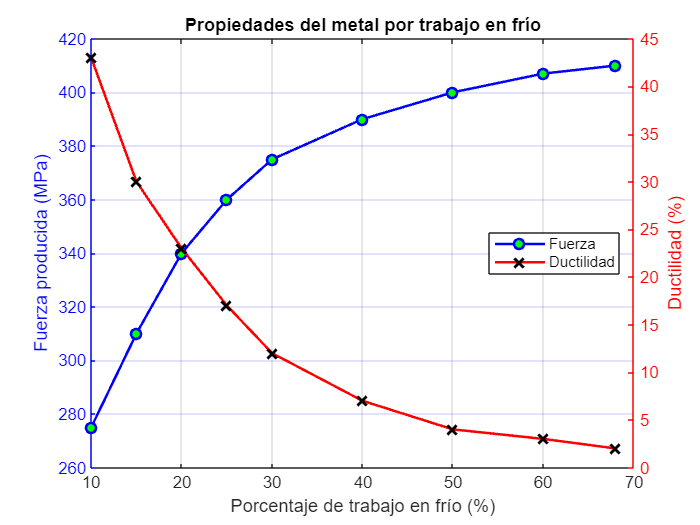

% Vector para el Porcentaje de trabajo en frío (Eje X)
trabajo_frio = [10, 15, 20, 25, 30, 40, 50, 60, 68];

% Vector para la Fuerza producida (Eje Y izquierdo)
fuerza = [275, 310, 340, 360, 375, 390, 400, 407, 410];

% Vector para la Ductilidad (Eje Y derecho)
ductilidad = [43, 30, 23, 17, 12, 7, 4, 3, 2];

% Gráfica
figure;

% Eje Y Izquierdo
yyaxis left;
plot(trabajo_frio, fuerza, "b-o", "LineWidth", 1.5 , "MarkerFaceColor","g","DisplayName","Fuerza");
ylabel("Fuerza producida (MPa)");
ax = gca; % Manejador (Handle)
ax.YColor = "b";

% Eje Y Derecho
yyaxis right;
plot(trabajo_frio, ductilidad, "r-x", "LineWidth", 1.5, "MarkerSize", 8,"DisplayName","Ductilidad","MarkerEdgeColor","k");
ylabel("Ductilidad (%)");
ax = gca;
ax.YColor = "r";

% Textos
title("Propiedades del metal por trabajo en frío");
xlabel("Porcentaje de trabajo en frío (%)");

legend("Location","east");
grid on;

### Ejercicio 4

En la figura adjunta se muestra una viga apoyada sobre soportes, sometida a una carga $\mathit{\mathbf{w}}$ con distribución constante sobre la mitad de su longitud.

**Figura 2.** Viga apoyada sobre soportes.

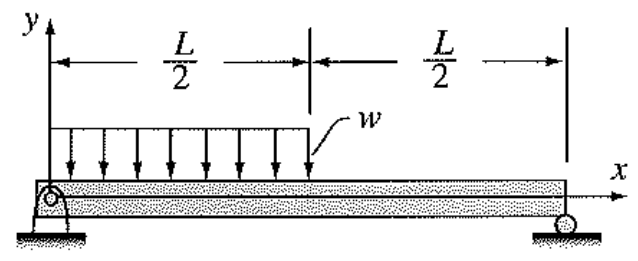

*Tomado de MATLAB: Introducción con ejemplos prácticos de Amos Gilat.*

En este caso, la deflexión $y$ en función de $x$ viene dada por las ecuaciones:

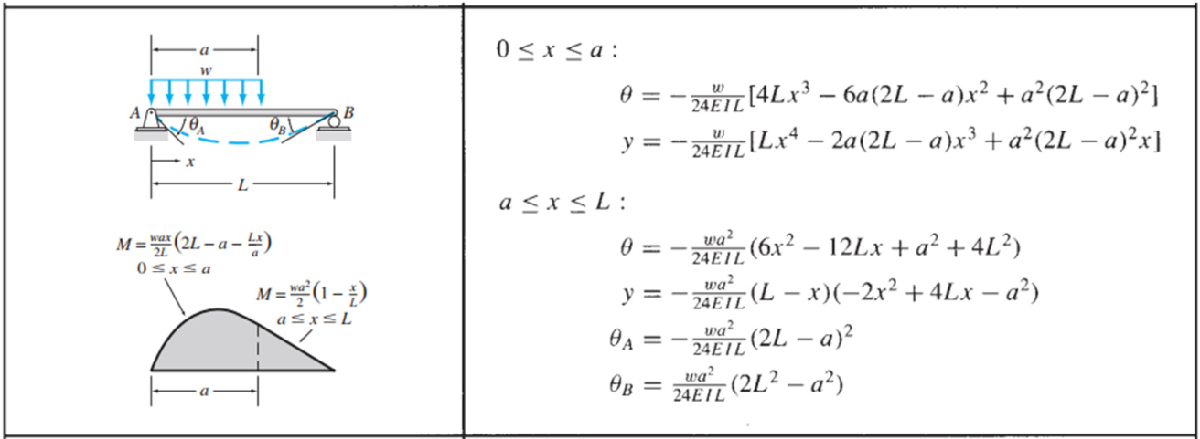

$y=\frac{-\textrm{wx}}{384\textrm{EI}}\left(16x^3 -24{\textrm{Lx}}^2 +9L^3 \right)$ para $0\le x\le \frac{L}{2}$

$y=\frac{-\textrm{wx}}{384\textrm{EI}}\left(8x^3 -24{\textrm{Lx}}^2 +17L^2 x-L^3 \right)$ para $\frac{L}{2}\le x\le L$

donde $E$ es el módulo de elasticidad, $I$ el momento de inercia y $L$ la longitud de la viga. La viga que se muestra en la figura posee las siguientes características: $L=20\;\mathrm{m}$, $E=200\times {10}^9 \;\textrm{Pa}$ (acero), $I=348\times {10}^{-6} \;{\mathrm{m}}^4$ y $w=5\times {10}^3 \;\mathrm{N}/\mathrm{m}$.

Represente gráficamente la deflexión de la viga $y$ en función de $x$.

*Ejercicio tomado de Gilat, 2005.*

### Solución

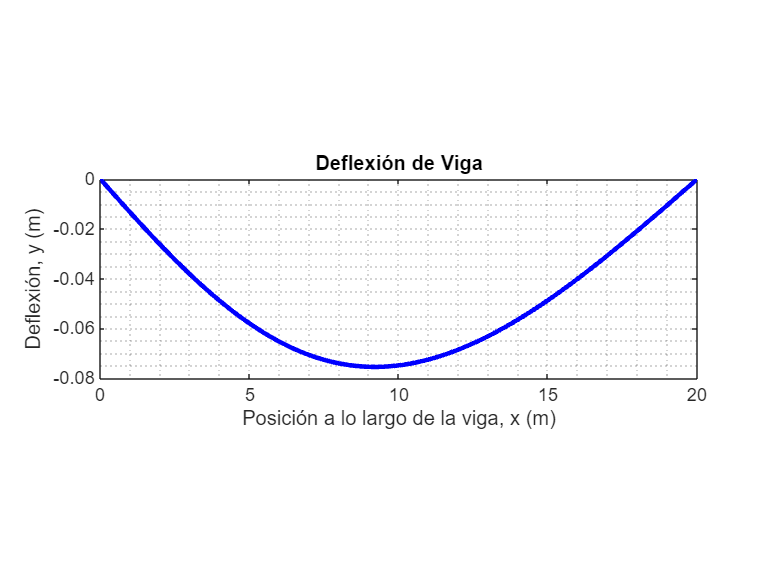

L = 20;         % Longitud de viga (m)
a = L/2;        % Longitud de carga distribuida (m)
E = 200e9;      % Módulo de elasticidad (Pa)
I = 348e-6;     % Momento de inercia (m^4)
w = 5e3;        % Carga distribuida (N/m)

x = linspace(0, L, 500);

y = zeros(size(x));

idx1 = (x <= a);
idx2 = (x > a);

x1 = x(idx1);
x2 = x(idx2);

y(idx1) = - (w./(24.*E.*I.*L)) .* ((L.*x1.^4 - 2.*a.*(2.*L-a) .* x1.^3 + a.^2.*(2.*L-a).^2 .* x1));

y(idx2) = - (w.*a.^2./(24.*E.*I.*L)) .* (L-x2) .* (-2.*x2.^2 +4.*L.*x2 -a.^2);
figure;

plot(x, y, "b-", "LineWidth", 2.5);

title("Deflexión de Viga");
xlabel("Posición a lo largo de la viga, x (m)");
ylabel("Deflexión, y (m)");
grid minor;
pbaspect([3 1 1]);
m = gca;
exportgraphics(m,"deflexión.png");

## Gráficas en 3-D

### Ejercicio 1

Cree vectores $\mathit{\mathbf{x}}$ y $\mathit{\mathbf{y}}$ desde -5 hasta +5 con un espaciamiento de 0.5. Use la función `meshgrid` para mapear $\mathit{\mathbf{x}}$ y $\mathit{\mathbf{y}}$ en dos nuevas matrices bidimensionales llamadas $\mathit{\mathbf{X}}$ y $\mathit{\mathbf{Y}}$. Use sus nuevas matrices para calcular el vector $\mathit{\mathbf{Z}}$, con magnitud


$$Z=\textrm{sen}\left(\sqrt{X^2 +Y^2 }\right)$$


- Use la función de graficación `mesh` para crear una gráfica tridimensional de $\mathit{\mathbf{Z}}$.

- Use la función de graficación `surf` para crear una gráfica tridimensional de $\mathit{\mathbf{Z}}$. Compare los resultados que obtuvo con una sola entrada ($\mathit{\mathbf{Z}}$) con los obtenidos con entradas para las tres dimensiones $\left(\mathit{\mathbf{X}},\mathit{\mathbf{Y}},\mathit{\mathbf{Z}}\right)$.

- Modifique su gráfica de superficie con sombreado interpolado. Intente usar diferentes mapas de colores.

- Genere una gráfica de contorno de $\mathit{\mathbf{Z}}$.

- Genere una combinación de gráficas de superficie y de contorno de $\mathit{\mathbf{Z}}$.

**Recomendación:** Utilizar las funciones `meshgrid`, `mesh`, `surf`, `contour`, `surfc` y `colormap` (consultar la documentación si es necesario).

*Ejercicio tomado de Moore, 2007.*

### Solución

x = -5:0.5:5;
y = -5:0.5:5;

[X, Y] = meshgrid(x, y);

Z = sin(sqrt(X.^2 + Y.^2));

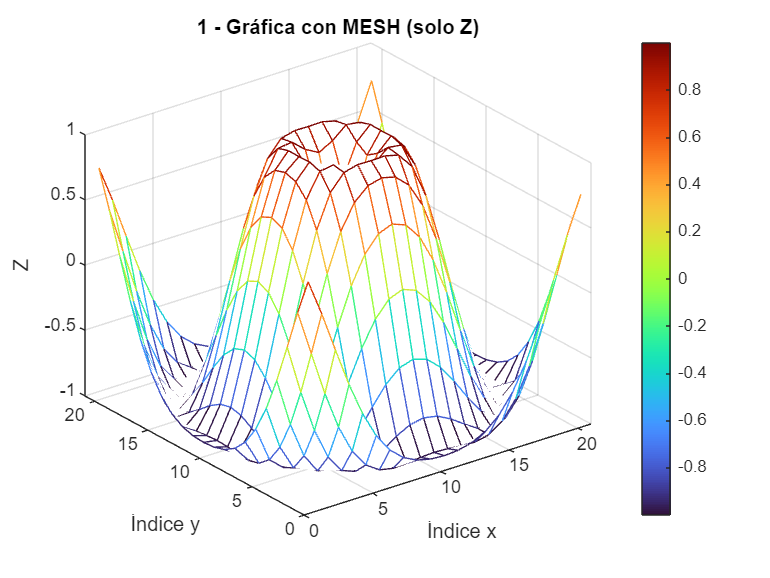

% 1. Gráfica con mesh
figure("Name","Gráfica con Mesh")
mesh(Z)
colormap turbo
title("1 - Gráfica con MESH (solo Z)")
xlabel("Índice x")
ylabel("Índice y")
zlabel("Z")
colorbar

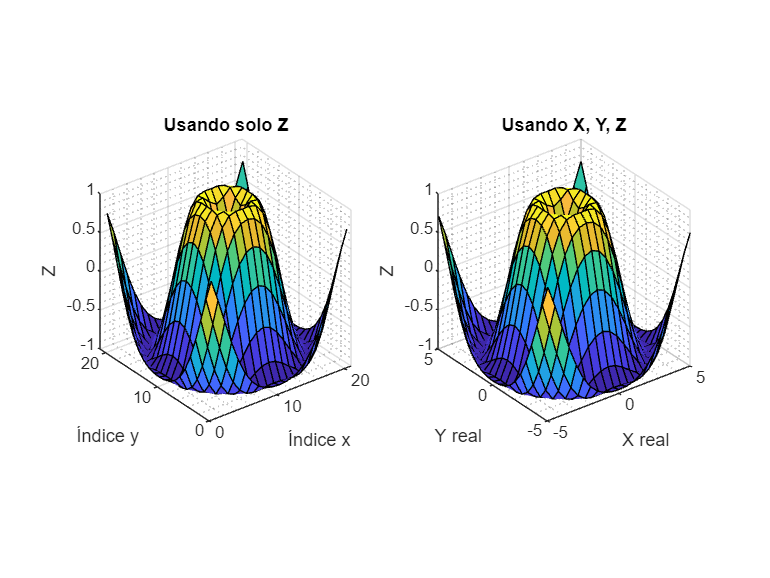

% 2. Gráficas con surf (comparación)
% Usando solo Z
figure("Name","Surf con solo Z")
colormap parula
subplot(1,2,1)
surf(Z)
title("Usando solo Z")
xlabel("Índice x")
ylabel("Índice y")
zlabel("Z")
axis("square");
grid minor

% Usando X, Y, Z
subplot(1,2,2)
surf(X, Y, Z)
title("Usando X, Y, Z")
xlabel("X real")
ylabel("Y real")
zlabel("Z")
axis("square");
grid minor

% Nota: observar diferencia en los ejes x e y

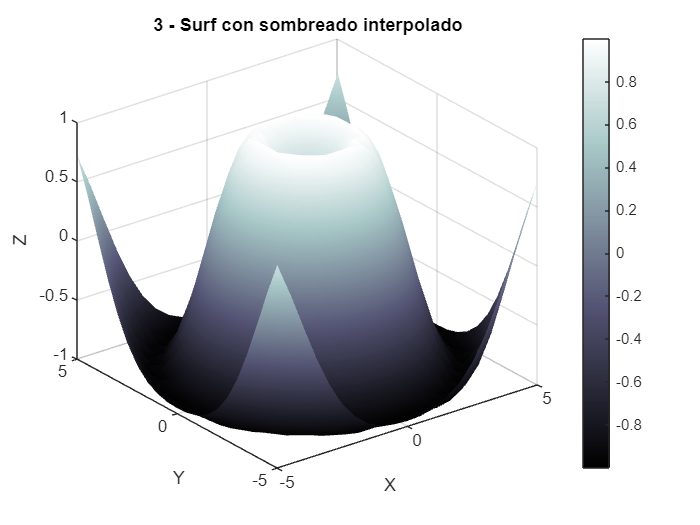

% 3.1. Superficie con sombreado interpolado y mapas de colores
figure("Name","Superficie con Sombreado y Colores")
surf(X, Y, Z)
shading interp
colormap bone
title("3 - Surf con sombreado interpolado")
xlabel("X")
ylabel("Y")
zlabel("Z")
colorbar

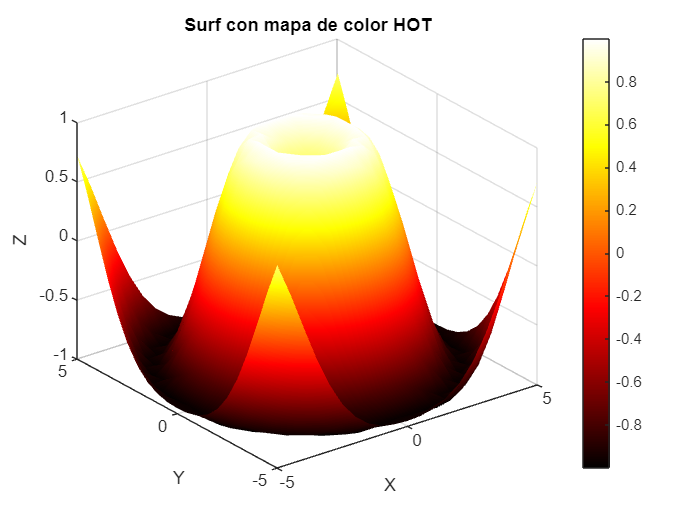

% 3.2. Figura adicional con mapa de color diferente
figure("Name","Mapa de Color Alternativo")
surf(X, Y, Z)
shading interp
colormap(hot)
title("Surf con mapa de color HOT")
xlabel('X')
ylabel('Y')
zlabel('Z')
colorbar

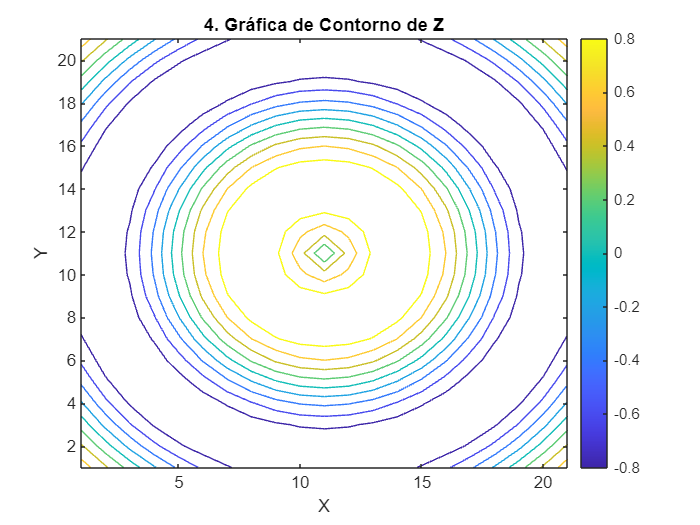

% 4. Gráfica de contorno
figure("Name","Gráfica de Contorno")
contour(Z)
title("4. Gráfica de Contorno de Z")
xlabel('X')
ylabel('Y')
colorbar

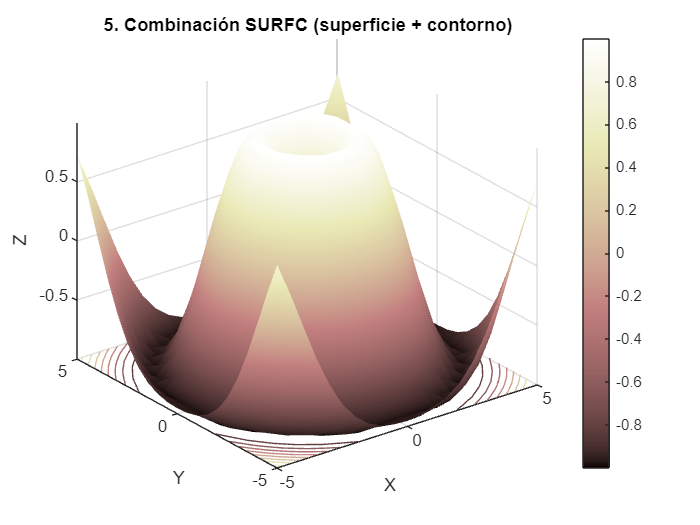

% 5. Combinación superficie-contorno
figure("Name","Combinación Superficie-Contorno")
surfc(X, Y, Z)  % Función combinada surfc
shading interp
colormap pink
title("5. Combinación SURFC (superficie + contorno)")
xlabel('X')
ylabel('Y')
zlabel('Z')
colorbar

### Ejercicio 2

La ley de los gases ideales relaciona presión, temperatura y volumen de un gas, de la forma:


$$P=\frac{\textrm{nRT}}{V}$$


donde $P$ es la presión en $\textrm{Pa}$, $n$ es el número de moles, $R=8\ldotp 31\;\mathrm{J}/\left(\textrm{mol}\cdot \mathrm{K}\right)$ es la constante de los gases, $T$ es la tempratura en grados $\mathrm{K}$ y $V$ es el volumen en ${\mathrm{m}}^3$.

Haga un gráfico en 3-D que muestre la variación de la presión (variable independiente, eje $z$) con respecto al volumen (variable independiente, eje $x$) y la temperatura (variable independiente, eje $y$) de un mol de gas. Los dominios del volumen y la temperatura son: $0\ldotp 5\times {10}^{-3} \le V\le 2\times {10}^{-3} \;{\mathrm{m}}^3$, y $273\le T\le 473\;\mathrm{K}$.

**Recomendación:** Utilizar la función `meshgrid` (consultar la documentación si es necesario).

*Ejercicio tomado de Gilat, 2005.*

### Solución

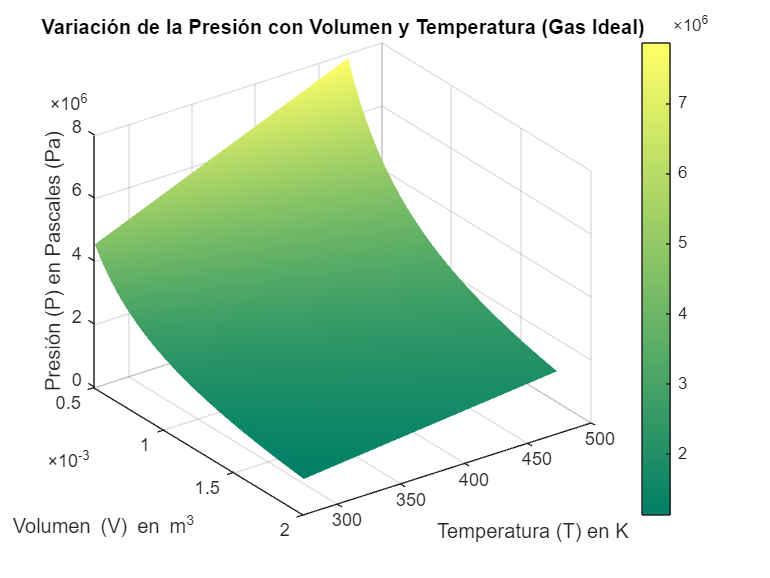

n = 1;      % Número de moles (mol)
R = 8.31;   % Constante de los gases ideales (J/(mol·K))
V = linspace(0.5e-3, 2e-3); % Dominio del Volumen (m^3)
T = linspace(273, 473);     % Dominio de la Temperatura (K)

[V_grid, T_grid] = meshgrid(V, T);

P = (n * R * T_grid) ./ V_grid; % Presión (en Pascales, Pa)
surf(V_grid, T_grid, P);
colormap summer;
shading interp;

title("Variación de la Presión con Volumen y Temperatura (Gas Ideal)");
xlabel("Volumen (V) en m^3");
ylabel("Temperatura (T) en K");
zlabel("Presión (P) en Pascales (Pa)");
colorbar

view([54 32]);

### Ejercicio 3

La tensión normal, $\sigma_{\textrm{xx}}$, debida a los momentos de flexión $M_z$ y $M_y$ en un punto $\left(y,z\right)$ en la sección transversal de una viga rectangular, viene dada por:


$$\sigma_{xx} =\frac{-M_z y}{I_{zz} }+\frac{-M_y z}{I_{yy} }$$


donde $I_{\textrm{zz}}$ e $I_{\textrm{yy}}$ son los momentos de inercia del área, definidos de la forma

$I_{zz} =\frac{1}{12}{bh}^3$     e     $I_{\textrm{yy}} =\frac{1}{12}{\textrm{hb}}^3$.

**Figura 3.** Tensión normal, $\sigma_{\textrm{xx}}$, de una viga rectangular sometida a los momentos de torsión $M_y$ y $M_z$.

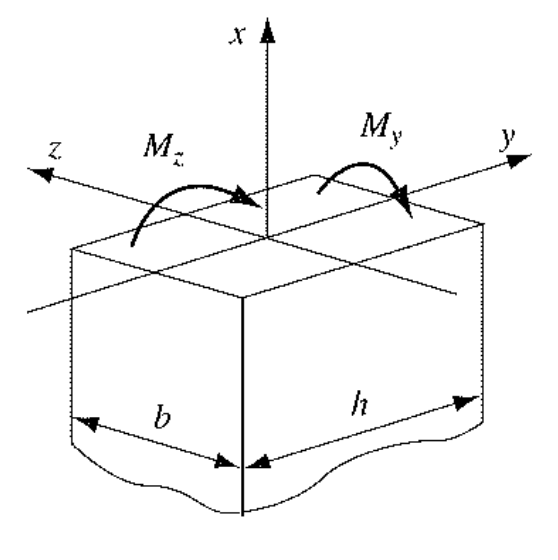

*Tomado de MATLAB: Introducción con ejemplos prácticos de Amos Gilat.*

Determine y represente la tensión normal en la superficie de la sección transversal de la viga mostrada en la figura. Utilice los valores: $h=40\;\mathrm{mm}$, $b=30\;\textrm{mm}$, $M_y =2500\;\mathrm{N}\cdot \mathrm{m}$ y $M_z =3600\;\mathrm{N}\cdot \mathrm{m}$. Dibuje las coordenadas $y$ y $z$ en el plano horizontal, y la tensión normal en la dirección vertical.

**Recomendación:** Utilizar la función `meshgrid` (consultar la documentación si es necesario).

*Ejercicio tomado de Gilat, 2005.*

### Solución

h = 40; % Altura en mm
b = 30; % Base en mm
My = 2500; % Momento de flexión alrededor del eje y (N·m)
Mz = 3600; % Momento de flexión alrededor del eje z (N·m)

h_m = h / 1000; % Altura en m
b_m = b / 1000; % Base en m

Iy = (1/12) * h_m * b_m^3; % Momento de inercia respecto al eje y (m^4)
Iz = (1/12) * b_m * h_m^3; % Momento de inercia respecto al eje z (m^4)

% Creación del Dominio y la Malla (Grid)
y = linspace(-b_m/2, b_m/2);
z = linspace(-h_m/2, h_m/2);

% Función meshgrid para crear las matrices que representan el plano y-z.
[Y_grid, Z_grid] = meshgrid(y, z);


$$\sigma_{xx} =\frac{-M_z y}{I_{zz} }+\frac{-M_y z}{I_{yy} }$$


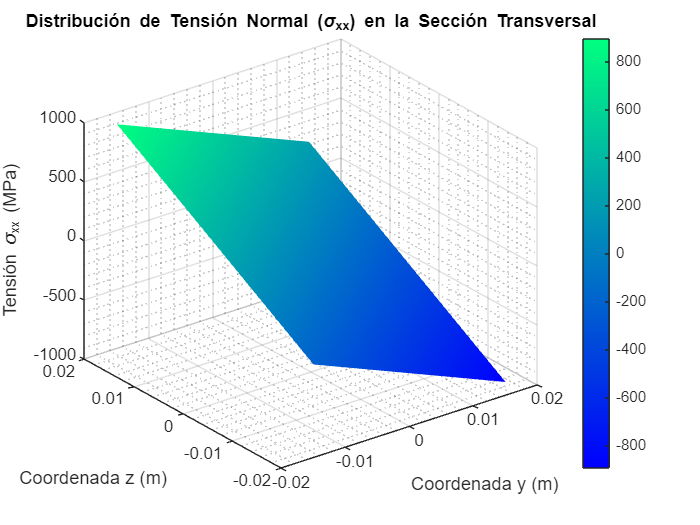

sigma_xx = -(Mz .* Y_grid) ./ Iz + (My .* Z_grid) ./ Iy;

sigma_xx_MPa = sigma_xx / 1e6;

figure("Name", "Tensión Normal en Viga", "NumberTitle", "off")
surf(Y_grid, Z_grid, sigma_xx_MPa);
colormap winter
shading interp;
colorbar;

title("Distribución de Tensión Normal (\sigma_{xx}) en la Sección Transversal");
xlabel("Coordenada y (m)");
ylabel("Coordenada z (m)");
zlabel("Tensión \sigma_{xx} (MPa)");
grid minor